Finding the Ton and Toff based on the plot

[x,Fs] = audioread("y.wav")

x =          0
    0.7437
    0.9185
    0.4499
   -0.2109
   -0.5318
   -0.3770
   -0.0632
    0.0280
   -0.1383


Fs = 8000

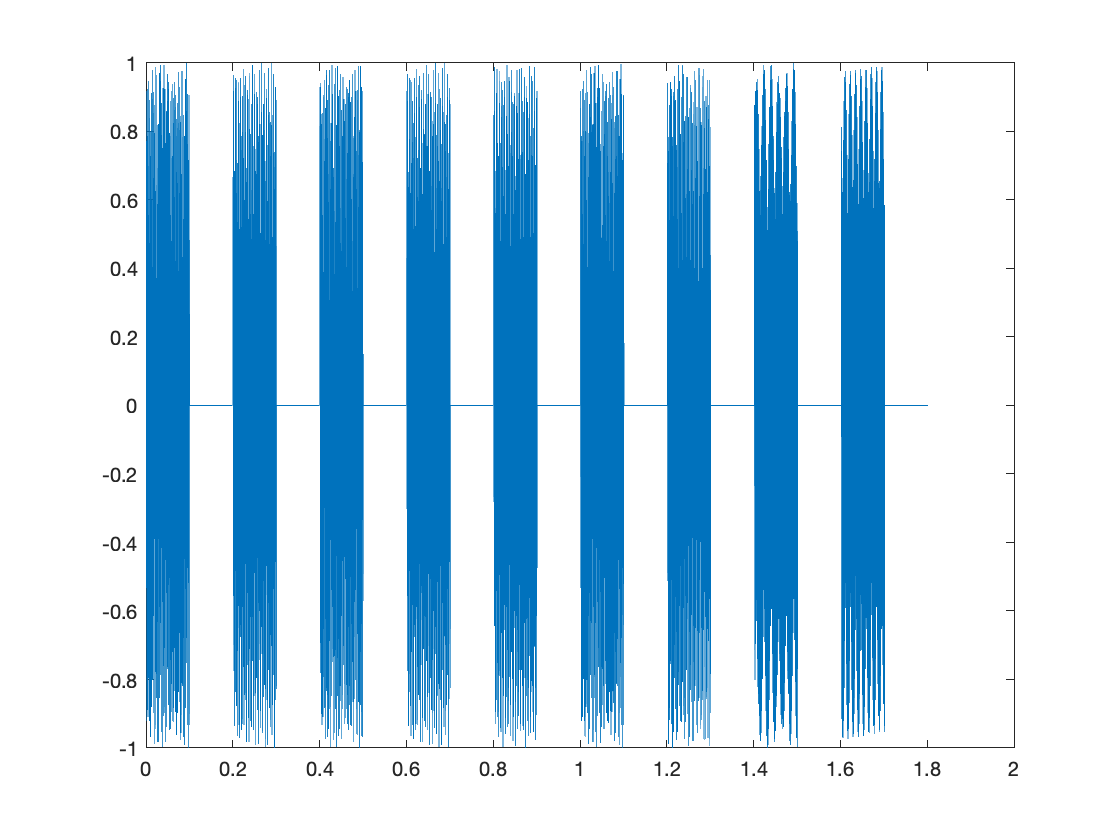

t=0:1/(Fs):numel(x(:,1))/Fs;
t(1)=[];
plot(t,x)

Due to the previous result, Ton=0.1s and Toff=0.1 as well.

x1= x(1:801);
x2= x(1604:2404);
x3= x(3206:4006);
x4= x(4808:5608);
x5= x(6410:7210);
x6= x(8012:8812);
x7= x(9614:10414);
x8= x(11216:12016);
x9= x(12818:13618);
fr=[941 697 697 697 770 770 770 852 852 852];
fc=[1336 1209 1336 1477 1209 1336 1477 1209 1336 1477];
fs = 8000;
Ts=1/fs;
Ton=0.1;
t=0:Ts:Ton;
y1=[];
y2=[];
y3=[];
y4=[];
y5=[];
y6=[];
y7=[];
y8=[];
y9=[];
for i=1:10
    y1_ = sin(2*pi*fr(i)*t);
    y2_ = sin(2*pi*fc(i)*t);
    y3_ = (y1_ + y2_)/2;
    %y3_(1)=[];
    r=corrcoef(x1,y3_);
    y1(end+1)=r(2,1);
%-------------------------
    r=corrcoef(x2,y3_);
    y2(end+1)=r(2,1);
%-------------------------
    r=corrcoef(x3,y3_);
    y3(end+1)=r(2,1);
%-------------------------
    r=corrcoef(x4,y3_);
    y4(end+1)=r(2,1);
%-------------------------
    r=corrcoef(x5,y3_);
    y5(end+1)=r(2,1);
%-------------------------
    r=corrcoef(x6,y3_);
    y6(end+1)=r(2,1);
%-------------------------
    r=corrcoef(x7,y3_);
    y7(end+1)=r(2,1);
%-------------------------
    r=corrcoef(x8,y3_);
    y8(end+1)=r(2,1);
%-------------------------
    r=corrcoef(x9,y3_);
    y9(end+1)=r(2,1);
end
y1

y1 =     0.4952   -0.0093    0.4997    0.0021   -0.0002    0.5089    0.0113    0.4934    1.0000    0.5038


[val1, idx1]=max(y1);
[val2, idx2]=max(y2);
[val3, idx3]=max(y3);
[val4, idx4]=max(y4);
[val5, idx5]=max(y5);
[val6, idx6]=max(y6);
[val7, idx7]=max(y7);
[val8, idx8]=max(y8);
[val9, idx9]=max(y9);
Ans=[idx1-1 idx2-1 idx3-1 idx4-1 idx5-1 idx6-1 idx7-1 idx8-1 idx9-1];
disp(Ans)

     8     1     0     1     9     8     4     2     3

